Система 

A = [-9, 31, -22, 15;
    0, -6, 4, 0;
    0, -10, 6, 0;
    -6, 17, -13, 9];
C = [2, -6, 4, -2;
    0, 4, -2, 0];
x0 = [1;2;3;4];
x1 = [3;5;-1;8];

fi = 4;
xi = 2;

Пара Q, R

Q = [16, 0, 0, 0;
    0, 16, 0, 0;
    0, 0, 16, 0;
    0, 0, 0, 16];
R = [4,0;
    0, 4];

Проверка пары A B на стабилизируемость

U = ctrb(Q, A);
rankU = rank(U);

Проверка пары Q A на обнаруживаемость

U = obsv(A, C);
rankU = rank(U);

Решение уравнения Риккати

M = -C'*inv(R)*C;

[P,K1,L5] = icare(A',[],Q,[],[],[],M)

P =   322.3289  -57.7090 -131.2262  189.9063
  -57.7090   29.8871   56.0061  -25.8077
 -131.2262   56.0061  111.7042  -60.4662
  189.9063  -25.8077  -60.4662  122.6923



K1 =

  0×4 empty double matrix



L5 =   -2.5915 + 1.7348i
  -2.5915 - 1.7348i
  -2.6240 + 0.0000i
 -16.7243 + 0.0000i




L = -P*C'*inv(R)

L =   -21.5486   -7.9041
    4.7751   -1.8840
    7.6849   -0.1540
  -11.8523   -4.4254


J = round(x0'*P*x0);

Построение графиков 

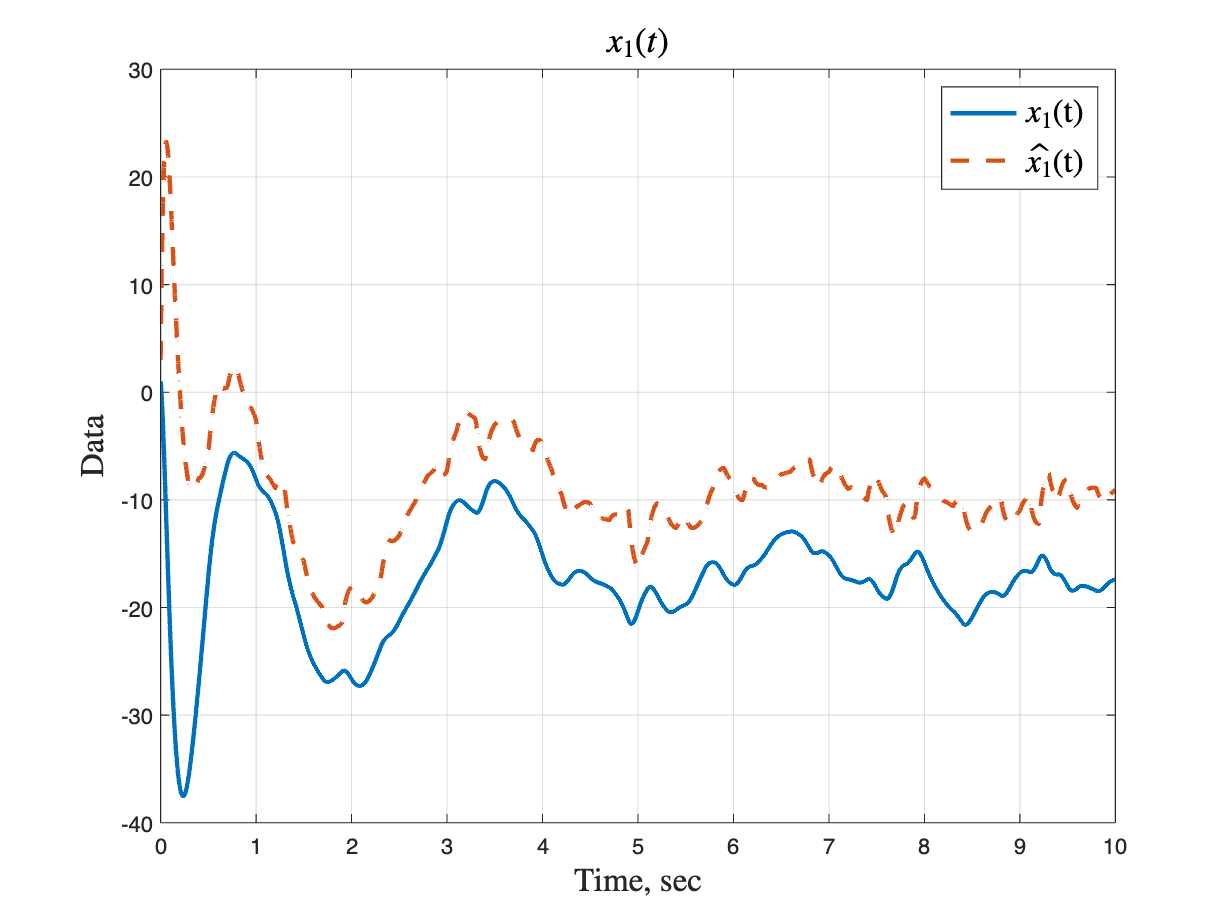

plot(out.x.Time, out.x.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,1), 'LineWidth', 2, 'LineStyle','--');
title('$x_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{1}$(t)","$\hat{x_{1}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

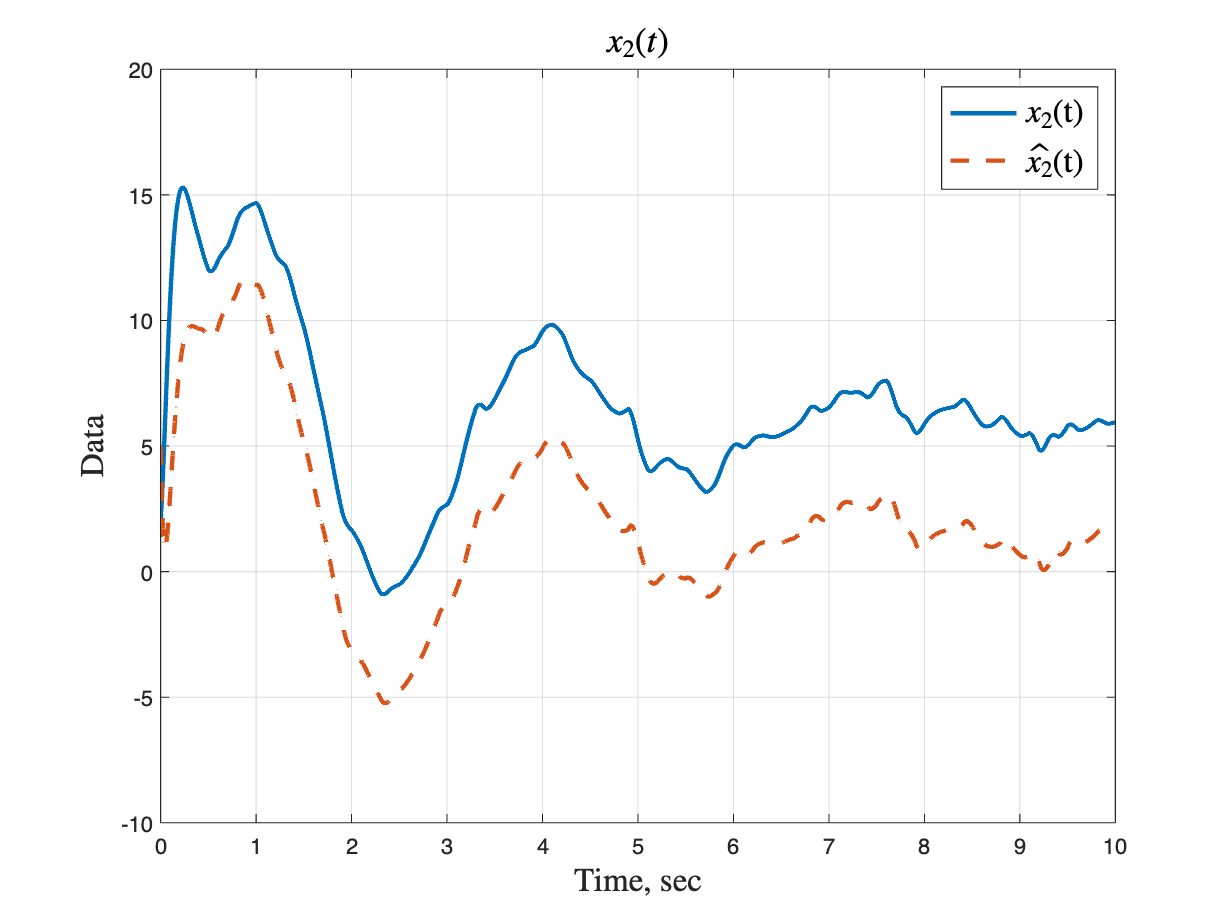


plot(out.x.Time, out.x.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,2), 'LineWidth', 2, 'LineStyle','--');
title('$x_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{2}$(t)","$\hat{x_{2}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

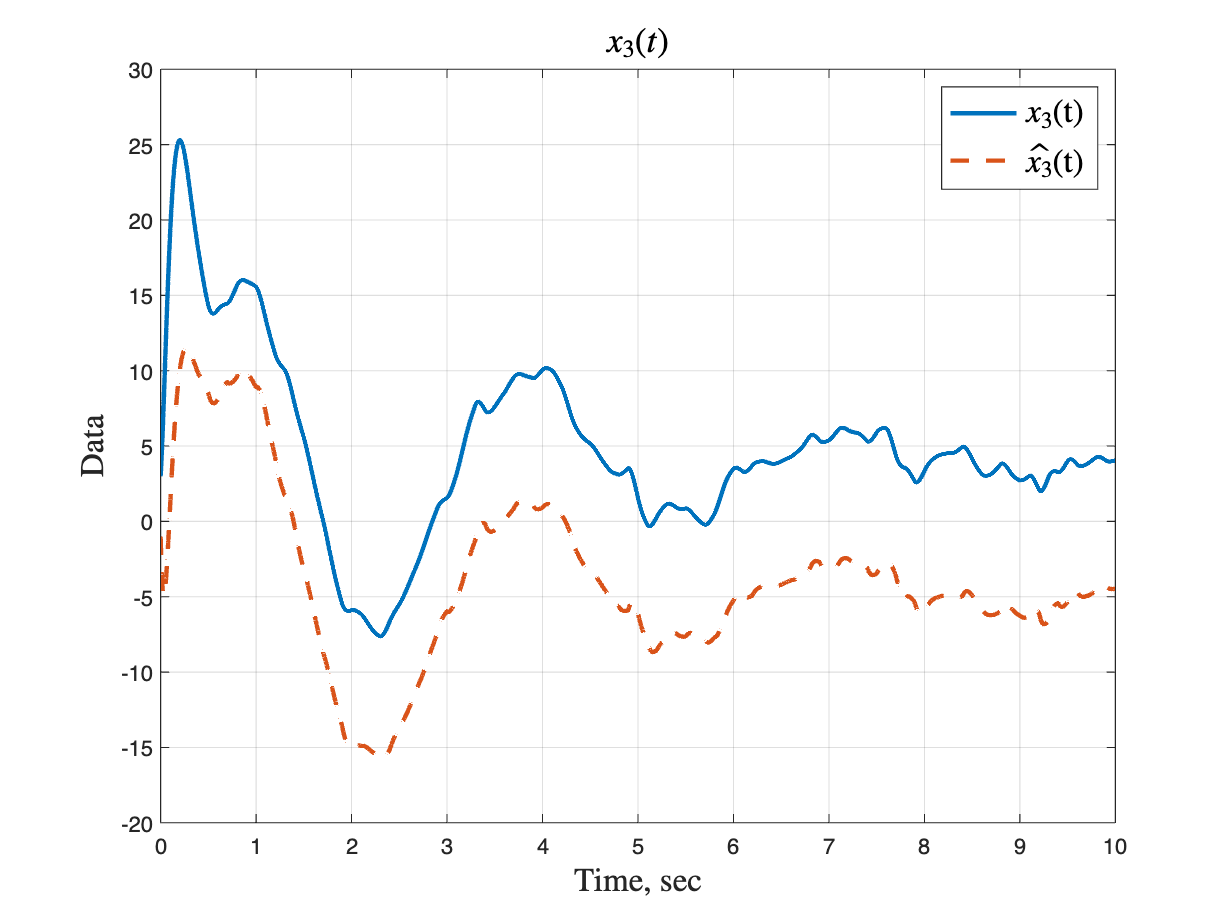


plot(out.x.Time, out.x.Data(:,3), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,3), 'LineWidth', 2, 'LineStyle','--');
title('$x_{3}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{3}$(t)","$\hat{x_{3}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

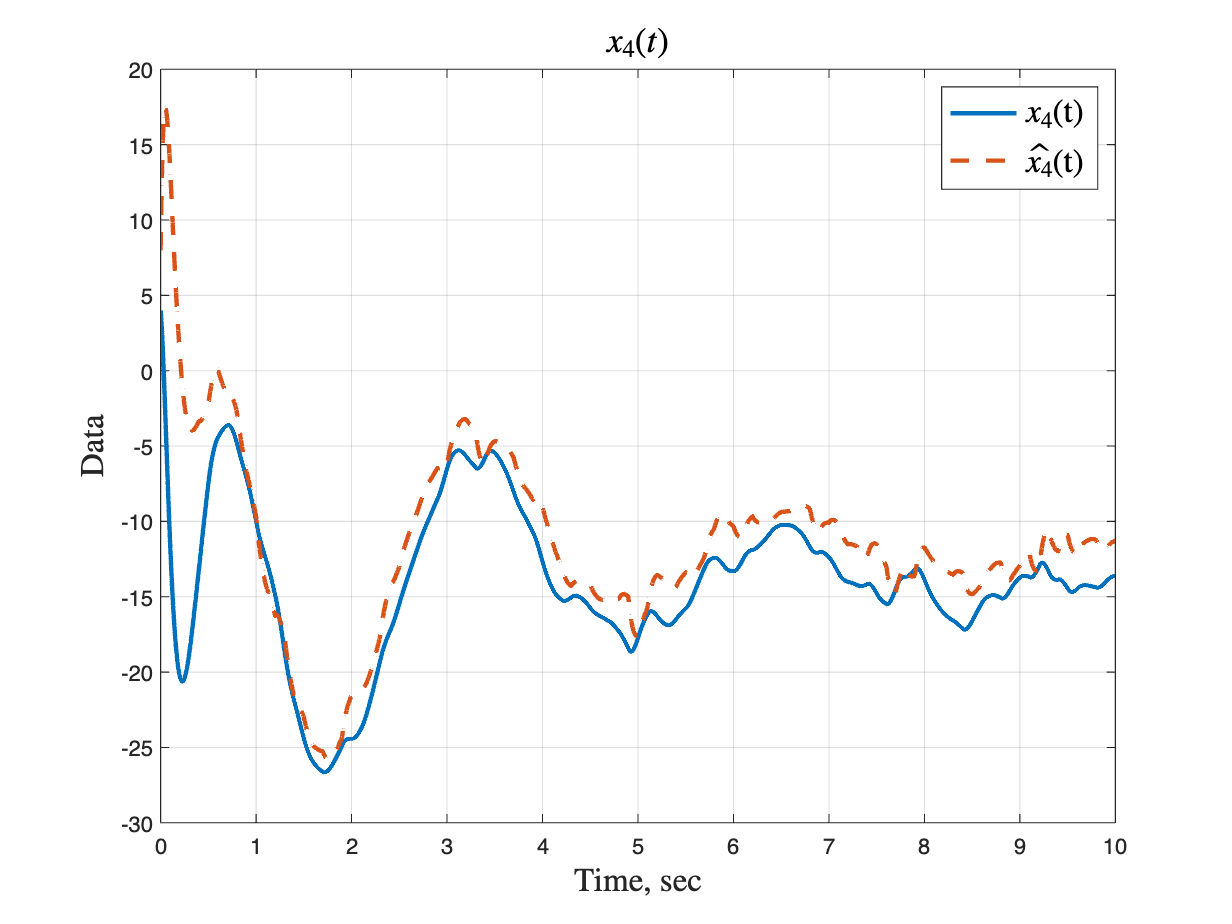


plot(out.x.Time, out.x.Data(:,4), 'LineWidth', 2);
hold on;
plot(out.xx.Time,out.xx.Data(:,4), 'LineWidth', 2, 'LineStyle','--');
title('$x_{4}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$x_{4}$(t)","$\hat{x_{4}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

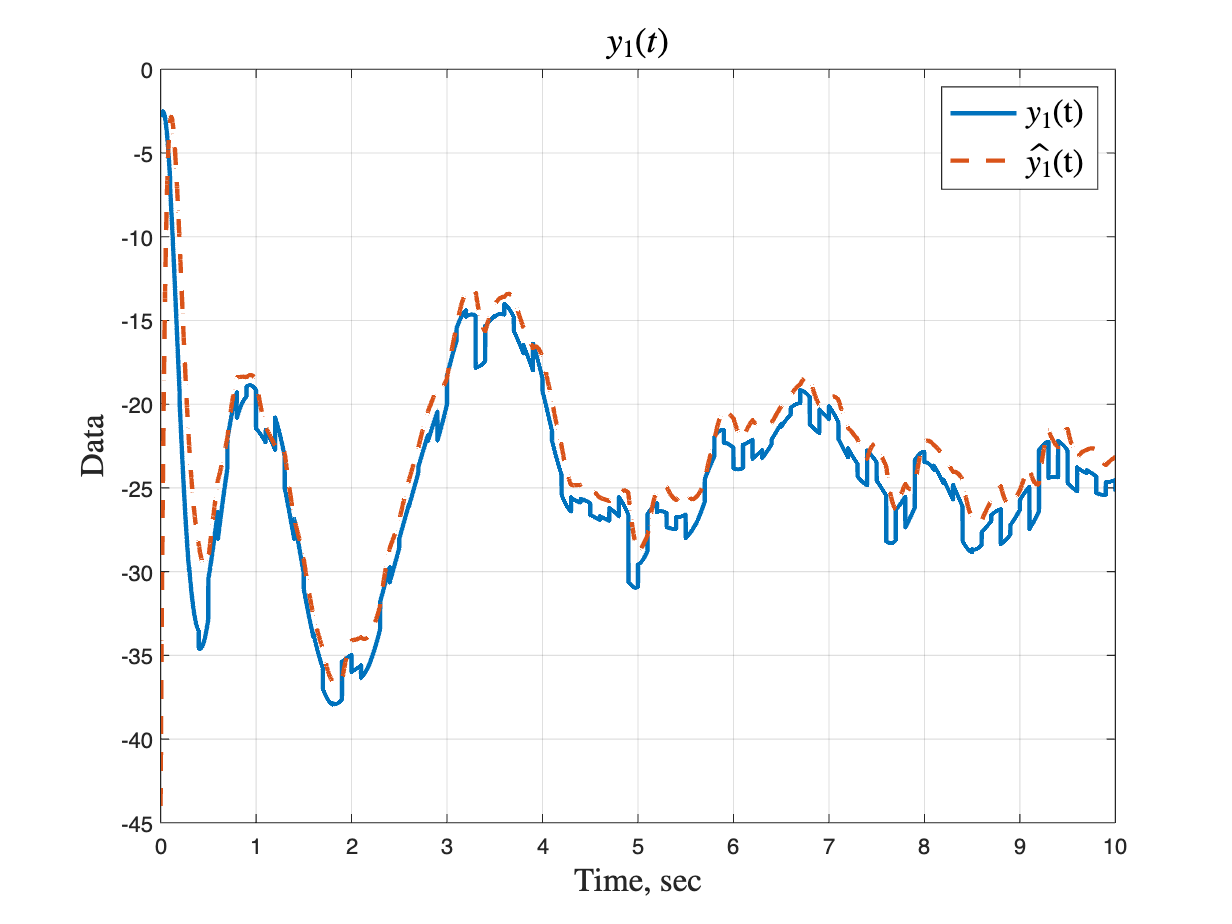


plot(out.y.Time, out.y.Data(:,1), 'LineWidth', 2);
hold on;
plot(out.yy.Time,out.yy.Data(:,1), 'LineWidth', 2, 'LineStyle','--');
title('$y_{1}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{1}$(t)","$\hat{y_{1}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;

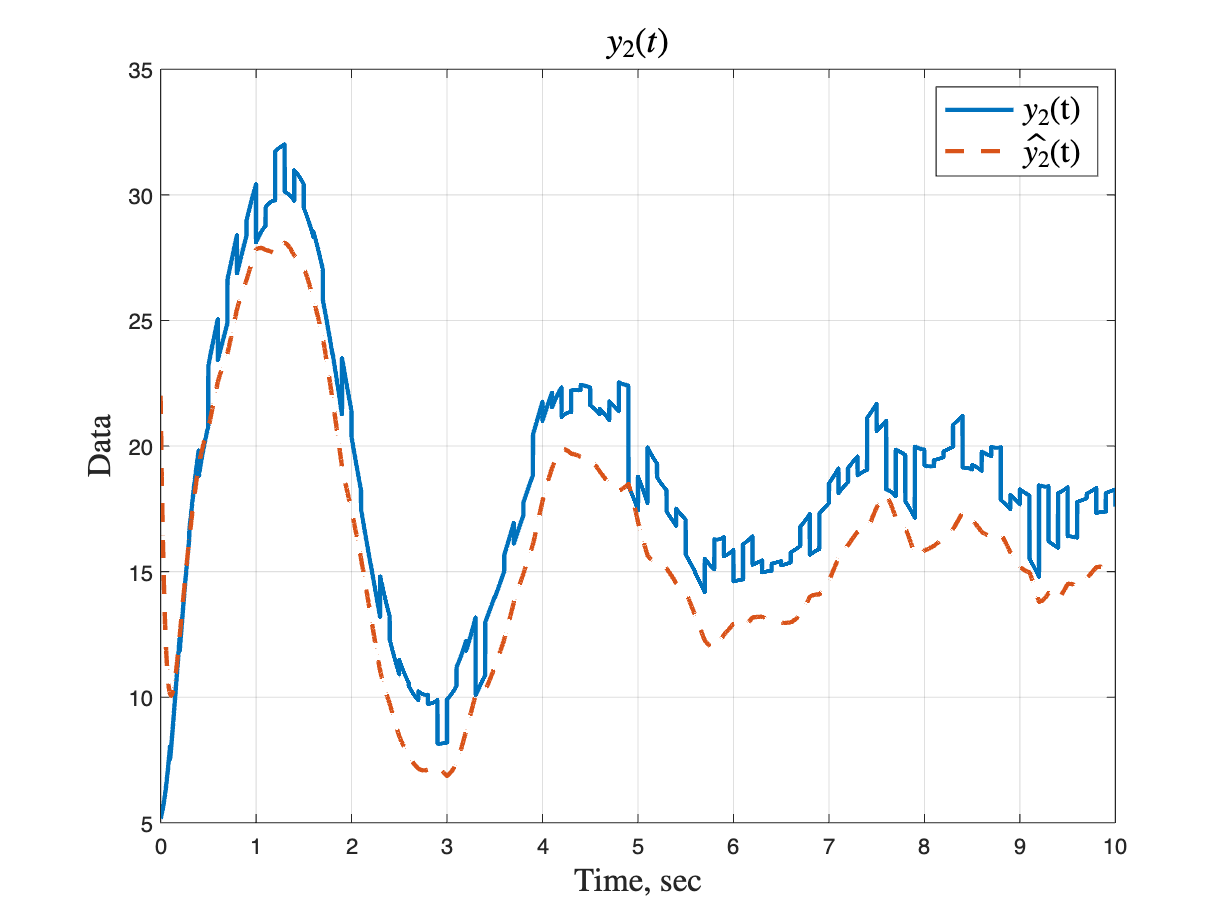


plot(out.y.Time, out.y.Data(:,2), 'LineWidth', 2);
hold on;
plot(out.yy.Time,out.yy.Data(:,2), 'LineWidth', 2, 'LineStyle','--');
title('$y_{2}(t)$','Interpreter', 'latex', 'FontSize', 16);
ylabel('Data', 'Interpreter', 'latex', 'FontSize', 15);
xlabel('Time, sec', 'Interpreter', 'latex', 'FontSize', 15);
legend("$y_{2}$(t)","$\hat{y_{2}}$(t)", 'Interpreter', 'latex', 'FontSize', 15);
grid on;
hold off;